**Cubic Splines**

Concept: 

Modeling data using a regression polynomial provides a smooth, continuous curve. However, regression polynomials tend to oscillate wildly and require massive numerical computations for polynomials of order greater than 10. The concept of splines was introduced to avoid these problems. 

A spline is a set of curves generated between data points such that they go through each data point and their derivatives are equal at each point to ensure smoothness. Imagine putting a bunch of nails into a board and weaving a stiff, but flexible plastic rod around the nails. The path taken by the rod is called a spline. 

Mathematically:

A spline is a set of funcitons fitted together at data points. The derivatives of the functions on either side of a data point are matched to provide smoothness to the overall spline.

Note: a spline is not a single function across the entire range. It is a set of functions each valid over a sub-range.

Polynomial Splines:

Splines use polynomials as convenient functions for modeling. Since many physical situations require 1st and 2nd derivatives, the third order polynomial is the most frequent form used. 

Cubic polynomials have the general form, f(x) = a + bx + cx^2 + dx^3.

To simplify calculations on each interval, replace x with [x - xi]. (This allows us to calculate the ai coefficients when x = xi, ai = yi).

Note: Si(x) covers the interval xi < x < xi+1.

The polynomial will now have the form, Si(x) + ai + bi(x - xi) + ci(x - xi)^2 + di(x - xi)^3.

The first and second derivatives of Si(x) are:

Si'(x) = bi + 2ci(x - xi) + 3di(x - xi)^2

Si"(x) = 2ci + 6di(x - xi)

The set of equations, [Si(x), Si'(x), Si"(x)], plus boundary conditions can then be used to determine values for the coefficients of each interval polynomial.

Spline Equations:

To find the equation of each polynomial, it is necessary to calculate the coefficients ai, bi, ci, di.

ai is deterimined to be yi.

ci can then be calculated by H * C = K

The H matrix can be inverted and multiplied by K to get C, e.g. C = H^-1 * K

Natural Cubic Spline:

The boundary conditions used most often assume that the second derivatives at the range ends are zero, i.e. c0 = cn = 0. This is called a natural cubic spline. 

The last two equations: 

bi = (ai+1 - ai)/hi - (ci+1 + 2ci)hi/3

di = (ci+1 - ci)/3hi

How to do calculations: 

- determine h values

- determine H and K matrices

- determine C matrix by inverting the H matrix and multiplying by K

- determine b and d coefficients and write spline equations

- graph spline

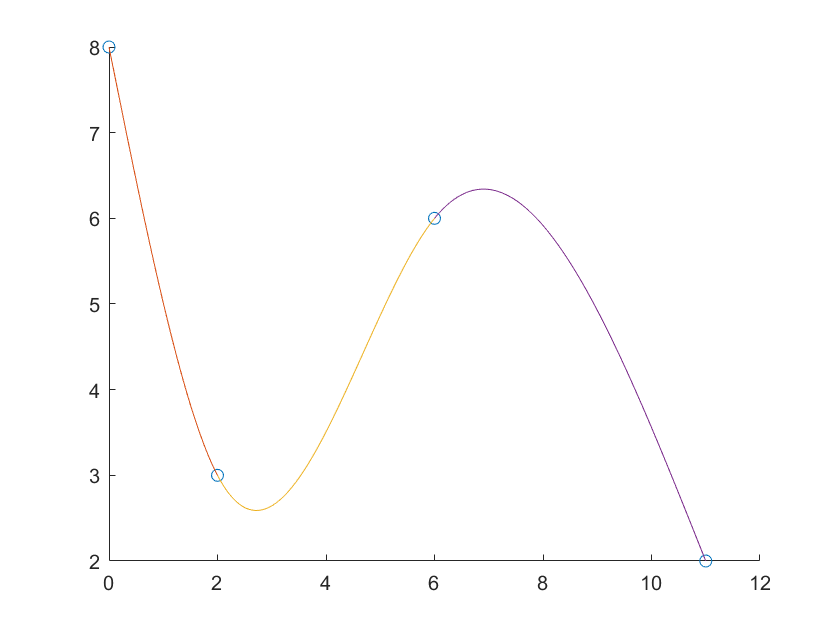

$$f = 0.16175\,x^{3}+2.2204\,10^{-16}\,x^{2}-3.147\,x+8.0$$

$$f = 0.9705\,{\left(x-2\right)}^{2}-1.206\,x-0.12037\,{\left(x-2\right)}^{3}+5.412$$

$$f = 0.78\,x-0.474\,{\left(x-6\right)}^{2}+0.0316\,{\left(x-6\right)}^{3}+1.32$$

%% Example 1: Using the data below, calculate a natural cubic spline model to fit the data.

x1 = [0, 2, 6, 11];
y = [8, 3, 6, 2];

S = cubic_spline(x1, y);

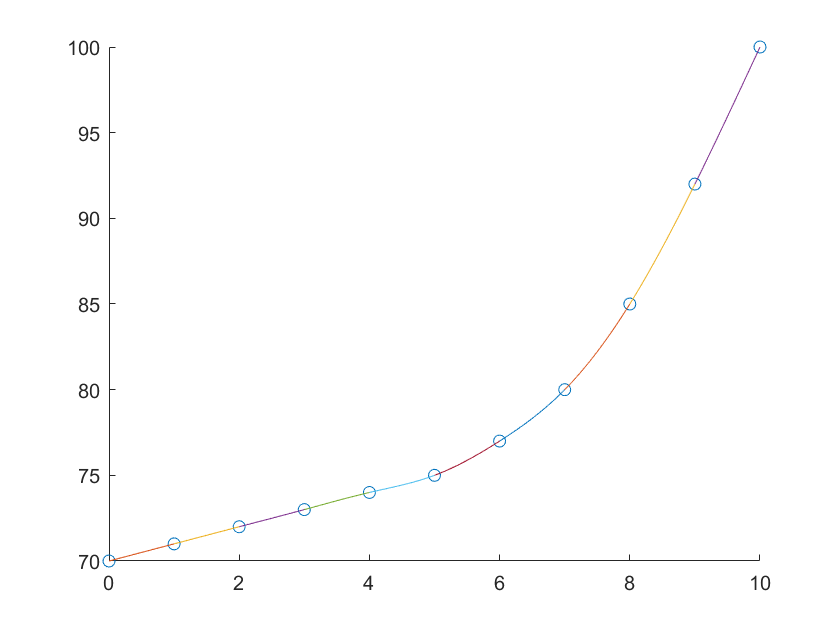

$$f = 0.0011631\,x^{3}+0.99884\,x+70.0$$

$$f = 1.0023\,x+0.0034894\,{\left(x-1\right)}^{2}-0.0058156\,{\left(x-1\right)}^{3}+69.998$$

$$f = 0.99186\,x-0.013958\,{\left(x-2\right)}^{2}+0.022099\,{\left(x-2\right)}^{3}+70.016$$

$$f = 1.0302\,x+0.052341\,{\left(x-3\right)}^{2}-0.082582\,{\left(x-3\right)}^{3}+69.909$$

$$f = 0.88718\,x-0.19541\,{\left(x-4\right)}^{2}+0.30823\,{\left(x-4\right)}^{3}+70.451$$

$$f = 1.4211\,x+0.72928\,{\left(x-5\right)}^{2}-0.15033\,{\left(x-5\right)}^{3}+67.895$$

$$f = 2.4286\,x+0.27828\,{\left(x-6\right)}^{2}+0.29311\,{\left(x-6\right)}^{3}+62.428$$

$$f = 3.8645\,x+1.1576\,{\left(x-7\right)}^{2}-0.022099\,{\left(x-7\right)}^{3}+52.949$$

$$f = 6.1134\,x+1.0913\,{\left(x-8\right)}^{2}-0.20471\,{\left(x-8\right)}^{3}+36.093$$

$$f = 7.6819\,x+0.47717\,{\left(x-9\right)}^{2}-0.15906\,{\left(x-9\right)}^{3}+22.863$$

z = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10];
T = [70, 71, 72, 73, 74, 75, 77, 80, 85, 92, 100];

S = cubic_spline(z, T);

0 = -kAdT/dx

k = 2.1

A = 10 ft * 20 ft = 10 * 20 * 12 ^2 = square inches

integrate with respect to position

calculate energy through each position

integral from 0 to 1 dq dx = integral from T to T0 -kAdt

q = -kA(T(z) - T0) / 1

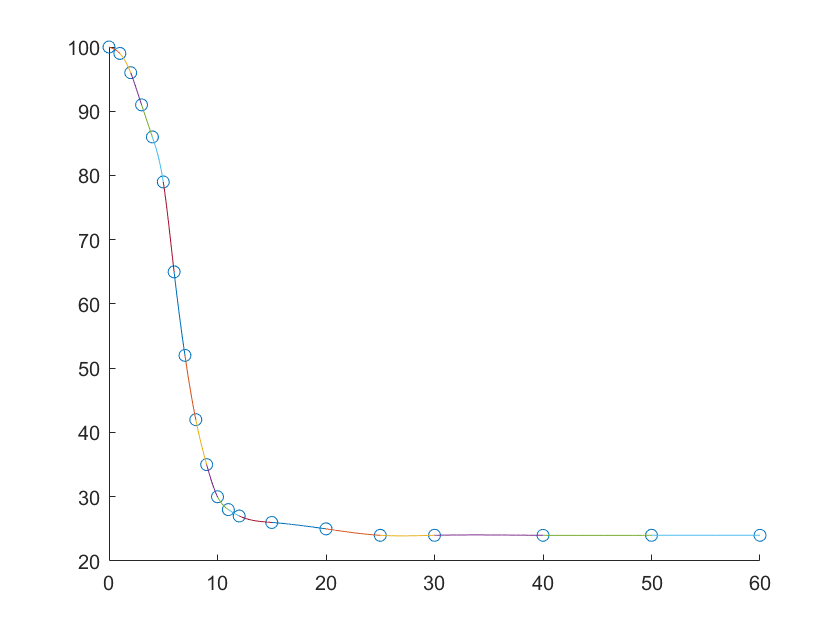

$$f = -0.39181\,x^{3}-0.60819\,x+100.0$$

$$f = 100.78-1.1754\,{\left(x-1\right)}^{2}-0.040964\,{\left(x-1\right)}^{3}-1.7836\,x$$

$$f = 0.55566\,{\left(x-2\right)}^{3}-1.2983\,{\left(x-2\right)}^{2}-4.2573\,x+104.51$$

$$f = 0.36868\,{\left(x-3\right)}^{2}-5.187\,x-0.18169\,{\left(x-3\right)}^{3}+106.56$$

$$f = 105.98-0.1764\,{\left(x-4\right)}^{2}-1.8289\,{\left(x-4\right)}^{3}-4.9947\,x$$

$$f = 2.4973\,{\left(x-5\right)}^{3}-5.6631\,{\left(x-5\right)}^{2}-10.834\,x+133.17$$

$$f = 1.8287\,{\left(x-6\right)}^{2}-14.669\,x-0.16019\,{\left(x-6\right)}^{3}+153.01$$

$$f = 1.3482\,{\left(x-7\right)}^{2}-11.492\,x+0.1435\,{\left(x-7\right)}^{3}+132.44$$

$$f = 1.7787\,{\left(x-8\right)}^{2}-8.3648\,x-0.41381\,{\left(x-8\right)}^{3}+108.92$$

$$f = 0.53723\,{\left(x-9\right)}^{2}-6.049\,x+0.51173\,{\left(x-9\right)}^{3}+89.441$$

$$f = 2.0724\,{\left(x-10\right)}^{2}-3.4393\,x-0.6331\,{\left(x-10\right)}^{3}+64.393$$

$$f = 0.17312\,{\left(x-11\right)}^{2}-1.1938\,x+0.020656\,{\left(x-11\right)}^{3}+41.132$$

$$f = 0.23509\,{\left(x-12\right)}^{2}-0.78556\,x-0.028116\,{\left(x-12\right)}^{3}+36.427$$

$$f = 0.00095631\,{\left(x-15\right)}^{3}-0.017952\,{\left(x-15\right)}^{2}-0.13415\,x+28.012$$

$$f = 0.0023994\,{\left(x-20\right)}^{3}-0.0036076\,{\left(x-20\right)}^{2}-0.24195\,x+29.839$$

$$f = 0.032383\,{\left(x-25\right)}^{2}-0.09807\,x-0.0025538\,{\left(x-25\right)}^{3}+26.452$$

$$f = 0.034226\,x-0.0059237\,{\left(x-30\right)}^{2}+0.00025011\,{\left(x-30\right)}^{3}+22.973$$

$$f = 0.0015797\,{\left(x-40\right)}^{2}-0.0092146\,x-0.000065819\,{\left(x-40\right)}^{3}+24.369$$

$$f = 0.0026328\,x-0.00039491\,{\left(x-50\right)}^{2}+0.000013164\,{\left(x-50\right)}^{3}+23.868$$

t = [0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 15, 20, 25, 30, 40, 50, 60];
C = [100, 99, 96, 91, 86, 79, 65, 52, 42, 35, 30, 28, 27, 26, 25, 24, 24, 24, 24, 24];
P = [7, 6.9, 6.8, 6.5, 6.1, 6, 5.8, 5.7, 5.5, 5.4, 5.3, 5.2, 5.1, 5, 4.9, 4.9, 4.8, 4.8, 4.8, 4.8];

SC = cubic_spline(t,C);

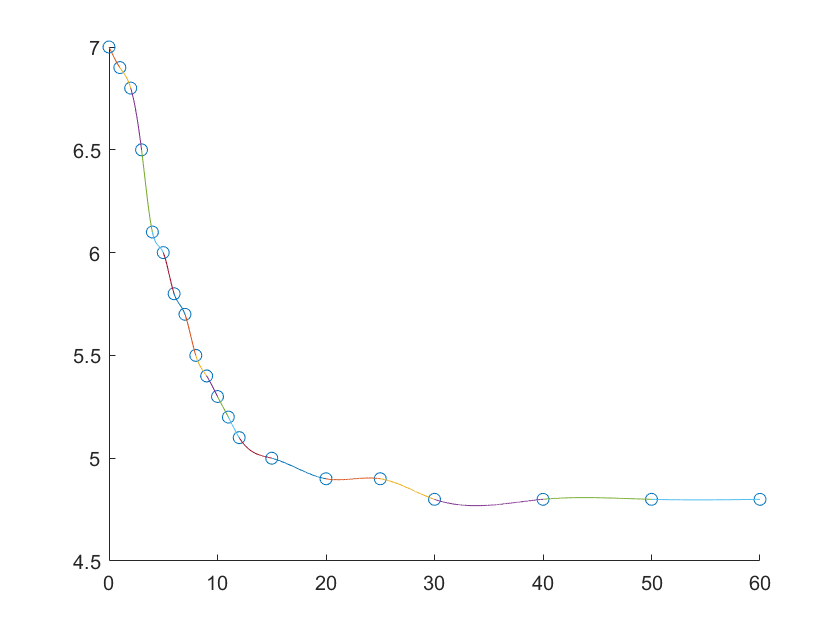

$$f = 0.010701\,x^{3}-0.1107\,x+7.0$$

$$f = 0.032104\,{\left(x-1\right)}^{2}-0.078597\,x-0.053507\,{\left(x-1\right)}^{3}+6.9786$$

$$f = 0.003327\,{\left(x-2\right)}^{3}-0.12842\,{\left(x-2\right)}^{2}-0.17491\,x+7.1498$$

$$f = 0.1402\,{\left(x-3\right)}^{3}-0.11844\,{\left(x-3\right)}^{2}-0.42176\,x+7.7653$$

$$f = 0.30216\,{\left(x-4\right)}^{2}-0.23804\,x-0.16412\,{\left(x-4\right)}^{3}+7.0522$$

$$f = 0.11629\,{\left(x-5\right)}^{3}-0.19021\,{\left(x-5\right)}^{2}-0.12608\,x+6.6304$$

$$f = 0.15867\,{\left(x-6\right)}^{2}-0.15762\,x-0.10105\,{\left(x-6\right)}^{3}+6.7457$$

$$f = 0.0879\,{\left(x-7\right)}^{3}-0.14447\,{\left(x-7\right)}^{2}-0.14343\,x+6.704$$

$$f = 0.11923\,{\left(x-8\right)}^{2}-0.16867\,x-0.050553\,{\left(x-8\right)}^{3}+6.8494$$

$$f = 0.014313\,{\left(x-9\right)}^{3}-0.032433\,{\left(x-9\right)}^{2}-0.08188\,x+6.1369$$

$$f = 0.010506\,{\left(x-10\right)}^{2}-0.10381\,x-0.0066981\,{\left(x-10\right)}^{3}+6.3381$$

$$f = 0.01248\,{\left(x-11\right)}^{3}-0.0095889\,{\left(x-11\right)}^{2}-0.10289\,x+6.3318$$

$$f = 0.02785\,{\left(x-12\right)}^{2}-0.08463\,x-0.0035838\,{\left(x-12\right)}^{3}+6.1156$$

$$f = 0.0006525\,{\left(x-15\right)}^{3}-0.0044042\,{\left(x-15\right)}^{2}-0.014292\,x+5.2144$$

$$f = 0.0053833\,{\left(x-20\right)}^{2}-0.0093959\,x-0.00070084\,{\left(x-20\right)}^{3}+5.0879$$

$$f = 0.00055084\,{\left(x-25\right)}^{3}-0.0051292\,{\left(x-25\right)}^{2}-0.008125\,x+5.1031$$

$$f = 0.0031334\,{\left(x-30\right)}^{2}-0.018104\,x-0.0001323\,{\left(x-30\right)}^{3}+5.3431$$

$$f = 0.0048742\,x-0.00083557\,{\left(x-40\right)}^{2}+0.000034815\,{\left(x-40\right)}^{3}+4.605$$

$$f = 0.00020889\,{\left(x-50\right)}^{2}-0.0013926\,x-6.9631\,10^{-6}\,{\left(x-50\right)}^{3}+4.8696$$

SP = cubic_spline(t,P);

Concepts and Skills to Know:

- explain what a spline model is, both conceptually and mathematically

- explain the advantages and disadvantages of a cubic spline for modeling

- define natural cubic spline

- use an electronic spreadsheet to calculate and graph a cubic spline model